# Customize the Border of a Table in a Presentation

To customize the border or a border segment of a table or table entry in a PPT API presentation, specify the border style, color, and width in an `mlreportgen.ppt.Border` format object and add the object to the `Style` property of an `mlreportgen.ppt.Table` or `mlreportgen.ppt.TabeEntry` object. This example specifies that the bottom border of the entry in the second row and second column is dashed, red, and has a width of three points.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myTEBorders.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table.

t = Table(magic(3));

Create a border object to customize the bottom border segment.

border = Border();
border.BottomStyle = "dash";
border.BottomColor = "red";
border.BottomWidth = "3pt";

Apply the custom border to the entry in the second column and second row.

tr2te2 = t.entry(2,2);
tr2te2.Style = [tr2te2.Style {border}];

Add a title and the table to the slide.

replace(slide,"Title","Table entry with custom borders");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the table in the generated presentation:

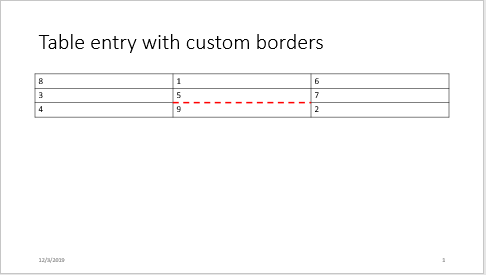

*Copyright 2019 The MathWorks, Inc.*